## Wing Design

clear
% Set default figure size (in inches)
set(groot, 'defaultFigureUnits', 'inches');
set(groot, 'defaultFigurePosition', [1, 1, 6, 4]); % Width = 6 inches, Height = 4 inches

% Set default font settings for all text in plots
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultAxesFontSize', 12); % Font size for axis labels and ticks
set(groot, 'defaultTextFontSize', 12); % Font size for text in the plot
set(groot, 'defaultAxesTitleFontSizeMultiplier', 1.2); % Slightly larger title
set(groot, 'defaultLegendFontSize', 11); % Font size for legend text

% Set default line and marker settings
set(groot, 'defaultLineLineWidth', 1.5); % Default line width
set(groot, 'defaultLineMarkerSize', 8); % Default marker size

% Set default box and grid
set(groot, 'defaultAxesBox', 'on'); % Enable box around plots by default
set(groot, 'defaultAxesGridLineStyle', '-'); % Solid grid lines
set(groot, 'defaultAxesXGrid', 'on'); % Enable grid for X axis
set(groot, 'defaultAxesYGrid', 'on'); % Enable grid for Y axis

global airfoil cruise1 cruise2 C_cruise Wto Swet_SrefWing Swet_SrefBody l_d bdes bodyDiameter Srefdes Damping tolerance Wpay
Wpay = 8.7176e3*9.81;
bodyDiameter = 6.38;
Damping = 0.03;
tolerance = 1e-4;
cruise1 = AirCondition();
cruise1.M = 0.83;
cruise1.h = convlength(28000, 'ft','m');

cruise2 = AirCondition();
cruise2.V = convvel(400, 'kts', 'm/s');
cruise2.h = convlength(18000, 'ft','m');
cruise2 = cruise2.calcM();

C_cruise = 0.5 ./ 3600;
Wto = 4.2990e5*9.81;
Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;

Srefdes = 548.7;

## 1.Design CL

CLdesC1 = 0.4623;
CLdesC2 = 0.3008;

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

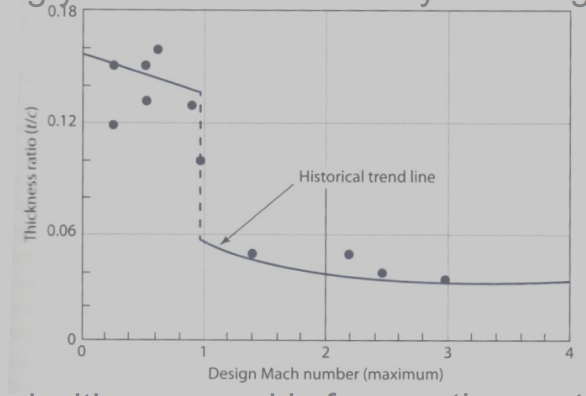

kA= 0.95;
Lambdades = 20*pi/180;
MDD = 0.85;

polarPath =  '../Airfoils/Airfoil polar data'; % Specify your directory path here
files = dir(polarPath); % Get a structure array with file information
polarNames = {files(~[files.isdir]).name}; % Extract names of all files, excluding directories

XYPath =  '../Airfoils/Airfoil XY data'; % Specify your directory path here
files = dir(XYPath); % Get a structure array with file information
XYNames = {files(~[files.isdir]).name}; % Extract names of all files, excluding directories
figure(4)
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    polarName = polarNames(i);
    shapeName = XYNames(i);
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    FF(i) = (1 + 0.6.*thisairfoil.t_c./thisairfoil.x_cm + 100 .*thisairfoil.t_c.^4) .* (1.34.*MDD.^0.18.*(cos(Lambdades)).^0.28);
    stallAngle(i) = thisairfoil.alphaSPos;
    CLmax(i) = max(thisairfoil.Cl);
    L_Ddes(i) = thisairfoil.L_DatCL(CLdesC1);
    t_c(i) = thisairfoil.t_c;
end

airfoilIdx = CLmax.*L_Ddes

airfoilIdx =    67.4807   68.9838   74.8436   85.4821   92.0619  107.0470  104.0407  114.4660  121.2740   53.3781  120.9334  134.6351  128.5125  102.6098  140.1716


airfoilData = table(polarNames', FF', t_c', stallAngle'.*180/pi, CLmax', L_Ddes', airfoilIdx', 'VariableNames', {'Name', 'Skin Friction Form Factor', 't/c', 'stallAngle','Clmax', 'L/D design', 'CLmax x L/D design'})

airfoilData = 15×7 table
                Name                 Skin Friction Form Factor      t/c       stallAngle    Clmax     L/D design    CLmax x L/D design
    _____________________________    _________________________    ________    __________    ______    __________    __________________

    {'xf-sc20010-il-1000000.csv'}              1.501               0.10003      13.75       1.2817      52.649            67.481      
    {'xf-sc20012-il-1000000.csv'}             1.5566               0.12003      15.25       1.3893      49.654            68.984      
    {'xf-sc20410-il-1000000.csv'}             1.3218              0.020035      12.75       1.4554      51.425            74.844      
    {'xf-sc20412-il-1000000.csv'}             1.3457         

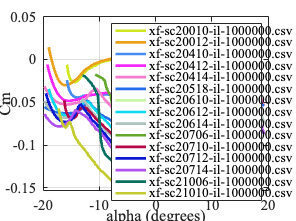

figure(7)
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    polarName = polarNames(i);
    shapeName = XYNames(i);
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    randomColor = rand(1, 3); % Generate a random RGB color
    plot(thisairfoil.alpha.*180/pi,thisairfoil.Cm,'LineWidth',2, 'Color', randomColor)
    hold on
end
legend(polarNames)
xlabel("alpha (degrees)")
ylabel("Cm")

t_cSweep = @(kA, Lambda, MDD, CL) cos(Lambda).*(kA - MDD.*cos(Lambda) - CL./(10.*cos(Lambda).^2))

t_cSweep = function_handle with value:
    @(kA,Lambda,MDD,CL)cos(Lambda).*(kA-MDD.*cos(Lambda)-CL./(10.*cos(Lambda).^2))


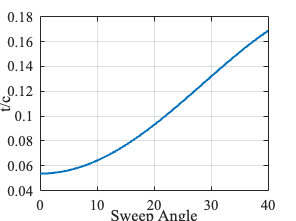

figure;
Lrange = linspace(0,40,100)*pi/180;
plot(Lrange*180/pi, t_cSweep(0.95,Lrange, 0.85, CLdesC1))
xlabel("Sweep Angle")
ylabel("t/c")
grid on

### Conclusion:

polarName = "xf-sc20712-il-1000000.csv";
shapeName = "sc20712.dat.txt";
airfoil = Airfoil();
airfoil = airfoil.readPolar(string(fullfile(polarPath, polarName)));
airfoil = airfoil.readShape(string(fullfile(XYPath, shapeName)));
airfoil = airfoil.interpShape(9);

## 3.Shape

1.Use MDO to get best geometry

    -Make sure it is applicable to double-tapered, swept wing

    -At each iteration inside MDO, calculate the optimum twist to give elliptical lift distribution

    -Use a validated wing weight estimation model

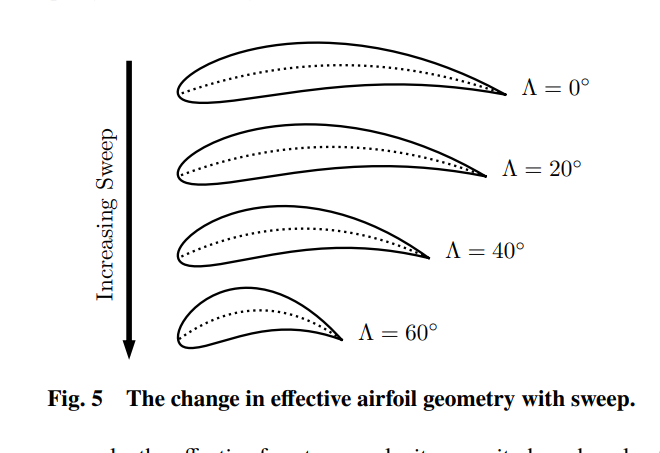

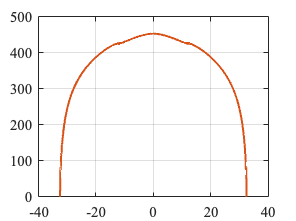

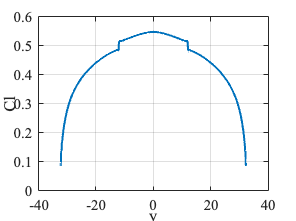

CL = 0.4028

CD = 0.0077

CLy =   -32.5000  -32.3700  -32.2400  -32.1100  -31.9800  -31.8500  -31.7200  -31.5900  -31.4600  -31.3300  -31.2000  -31.0700  -30.9400  -30.8100  -30.6800  -30.5500  -30.4200  -30.2900  -30.1600  -30.0300  -29.9000  -29.7700  -29.6400  -29.5100  -29.3800  -29.2500  -29.1200  -28.9900  -28.8600  -28.7300  -28.6000  -28.4700  -28.3400  -28.2100  -28.0800  -27.9500  -27.8200  -27.6900  -27.5600  -27.4300  -27.3000  -27.1700  -27.0400  -26.9100  -26.7800  -26.6500  -26.5200  -26.3900  -26.2600  -26.1300
    0.0928    0.0935    0.0879    0.1365    0.1364    0.1661    0.1700    0.1898    0.1955    0.2096    0.2160    0.2266    0.2330    0.2416    0.2477    0.2548    0.2605    0.2666    0.2719    0.2773    0.2822    0.2871    0.2915    0.2960    0.3001    0.3042    0.3081    0.3118    0.3154    0.3189    0.3223    0.3256    0.3288    0.3318    0.3348    0.3377    0.3406    0.3433    0.3460    0.3486    0.3512    0.3536    0.3561    0.3584    0.3608    0.3630    0.3653    0.3674    0.3696   


% Initial guess
% wing span fixed to 65
bdes = 65;
x0 = [10, 8, 5, 31*pi/180, 25*pi/180, 12, deg2rad(1.3)];
%x0 = [cr, ck, ct, Lambdain50, Lambdaout50, yk, maxtwist in radians]
% Design variables 
lb = x0.*0.5;
%lb(7) = deg2rad(3);
ub = x0.*1.5;
%ub(7) = deg2rad(3);
wing0 = x2wing(x0);
cruise1 = cruise1.init(wing0.cbar);
[CL, CD, CLy] = LLESwept(wing0, airfoil, cruise1)

%wingMDO(x0)
% Optimization options
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
% Run the optimization
[x_opt, fval] = fmincon(@wingMDO, x0, [], [], [], [], lb, ub, @constraintFunction, options);
wing_opt =  x2wing(x_opt);
wing_opt = wing_opt.calcSref();
figure(1)
clf;
subplot(2,1,1)
wing0.plotWing()
title("Initial")
axis equal
subplot(2,1,2)
wing_opt.plotWing()
title("Optimzed")
yline(bodyDiameter/2)
hold on
yline(-bodyDiameter/2)
axis equal

save("wing_opt.mat","wing_opt")

Analyse the aero characteristic of opt wing:

During cruise1:

%load("wing_opt.mat")
cruise1 = cruise1.init(wing_opt.cbar)
[CL1, CDi1, Cly1] = LLESwept(wing_opt, airfoil, cruise1)
CDF1 = CDFfun(cruise1.M, cruise1.Re, wing_opt, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody);
CDW1 = CDWfun(wing_opt,Cly1,cruise1.M,airfoil.t_c);
CDtotal1 = CDF1 + CDW1 + CDi1;

disp(["L/D: ", CL1/ CDtotal1])
disp(["CLclean: ", CL1])
disp(["Sref: ", wing_opt.SREF])
disp(["Maximum twist(degrees)", wing_opt.twist_max * 180/pi])
disp(["Inner sweep angle(degrees)", wing_opt.Lambdain50 * 180/pi])
disp(["Outer sweep angle(degrees)", wing_opt.Lambdaout50 * 180/pi])
disp(wing_opt)

## 4.Dihedral

-G17 presents a quantitative estimate

## 5.HLD

1.Calculate CLmax requirement at landing and takeoff

2.Select

## 6.Control Surfaces

## 7.Tailplane design

## 8.Nose shape optimization